# Project 1 (Community Solar Billing Simulator)

%{
Linear + Piecewise function
   originally from ES115 Engineering Computer Applications, Module 1 project bank, project 1
Author: Tori Testa
Version: 1.0
Date: 2026-03-30
Purpose:
   To compare the costs of two different electricity bill plans for amounts
   of energy (in kWh).
Input:
   -the start, end, and increment values for the energy (in kWh)
Output:
   -a graph displaying the monthly bill for Plan A vs energy usage and the
   monthly bill for Plan B vs energy usage.
   -a table displaying the cost for each plan at certain amounts of energy
   usage.
   -showing at how much energy usage the two plans cost the same amount of
   money.
   -a recommendation of which plan a customer should choose, based on the
   amount of energy use.
Engineering Algorithems:
   -
MATLAB tools/functions:
   -
%}

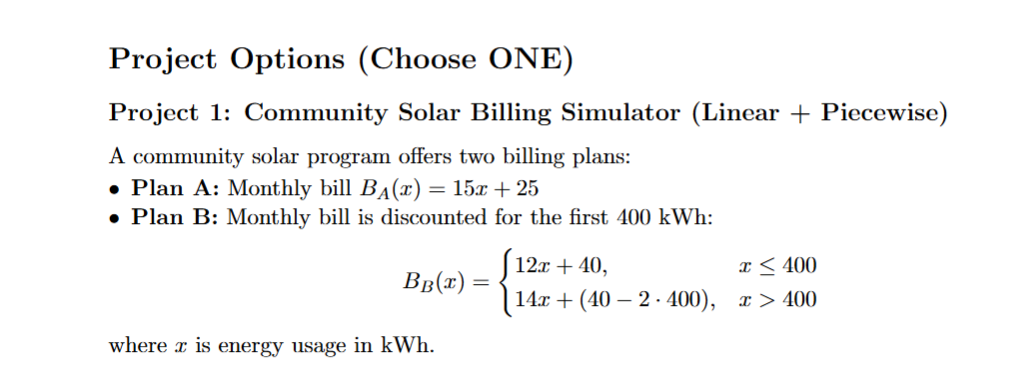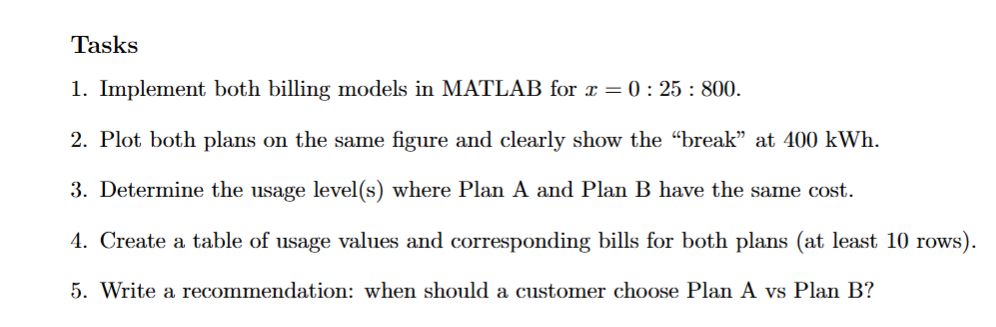

clc;
% defines a1, a2, and a3 as the values entered by the user into the userInput function
[a1,a2,a3] = userInput () 

a1 = 0

a2 = 25

a3 = 800

x = a1:a2:a3   % defines x as values between what the user entered, by the interval the user entered.

x =      0    25    50    75   100   125   150   175   200   225   250   275   300   325   350   375   400   425   450   475   500   525   550   575   600   625   650   675   700   725   750   775   800


PlanA = (15*x) + 25    % defines Plan A as 15x + 25

PlanA =           25         400         775        1150        1525        1900        2275        2650        3025        3400        3775        4150        4525        4900        5275        5650        6025        6400        6775        7150        7525        7900        8275        8650        9025        9400        9775       10150       10525       10900       11275       11650       12025



% Plan B is a piecewise function for defined x values.
PlanB = zeros(size(x)); 

% when x is less than/equal to 400 kWh, Plan B is 12x + 40
PlanB(x <= 400) = 12*x(x <= 400) + 40;  
% when x is greater than 400 kWh, Plan B is 14x - 760
PlanB(x > 400) = 14*x(x > 400) - 760;

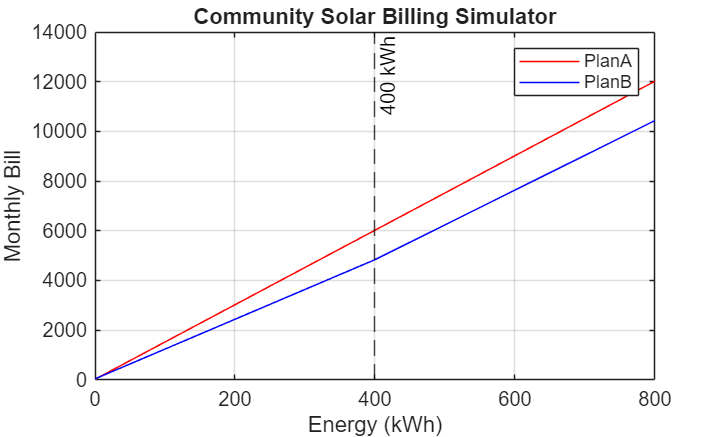

plot(x, PlanA, 'r-')     % plots plan A
hold on     % allows for plan A and plan B to be graphed on the same plot
plot(x, PlanB, 'b-')    % plots plan B

% creates a dashed line to clearly show the break in Plan B at x = 400 kWh
xline(400, '--k', '400 kWh')  
title('Community Solar Billing Simulator')    % creates a title for the plot
xlabel('Energy (kWh)')   %labels the x axis and shows the units
ylabel('Monthly Bill')   % labels the y axis
legend('PlanA','PlanB')  % includes a legend to show which plan corresponds to each line on the graph
grid on   % shows the gridlines of the plot
hold off  % means that nothing else is going to be graphed on the plot

% solving for where Plan A and Plan B intersect if x <= 400 kWh
% 15x + 25 = 12x + 40 , simplifies to:
x1 = (15) / (3);
% solving for where Plan A and Plan B intersect if x > 400 kWh
% 15x + 25 = 14x - 760 , simplifies to:
x2 = (-760 - 25) / (1);

solutions = [];
if x1 <= 400
    solutions = [solutions; x1];  
% the above defines the solution as a point where x1 is true for x <= 400 kWh
end
if x2 > 400
    solutions = [solutions; x2]; 
% the above defines the solution as a point where x2 is true for x > 400 kWh
end
% displays message of where Plan B and Plan A have the same cost per month
fprintf('Plan A and Plan B cost the same at %g kWh\n', solutions) 

Plan A and Plan B cost the same at 5 kWh


% creates a table of energy usage, the cost of Plan A per month, and 
% the cost of Plan B per month 
T = table(x', PlanA', PlanB', 'VariableNames', {'energy', 'PlanA','PlanB'})

T = 33×3 table
    energy    PlanA    PlanB
    ______    _____    _____

       0        25       40 
      25       400      340 
      50       775      640 
      75      1150      940 
     100      1525     1240 
     125      1900     1540 
     150      2275     1840 
     175      2650     2140 
     200      3025     2440 
     225      3400     2740 
     250      3775     3040 
     275      4150     3340 
     300      4525     3640 
     325      4900     3940 
     350      5275     4240 
     375      5650     4540 


% displays recommendation for when a customer should choose Plan A
fprintf('For energy use less than %g, kWh Plan A is better\n', solutions);

For energy use less than 5, kWh Plan A is better


% displays recommendation for when customers should choose Plan B
fprintf('For energy use greater than %g, kWh Plan B is advised\n', solutions);

For energy use greater than 5, kWh Plan B is advised


function [start, incr, stop] = userInput()  % creates a function allowing users to enter their own values
start = input('Enter the starting energy level'); % the first thing the user is prompted to enter
% if the user enters something that is negative or not a number, the graph starts at 0 kWh
if start < 0 
    start = 0; 
end
incr = input('Enter the increment'); % prompts the user to enter the increment it goes up by
% if the user enters a negative or non-number value, the increment will be 25 kWh
if incr < 0
    incr = 25;
end
stop = input('Enter the end value'); % prompts the user to enter the desired end value
% if the user enters a negative or non-number value, the graph ends at 800 kWh
if stop< start && stop < 0
    stop = 800;
end
end % ends the function